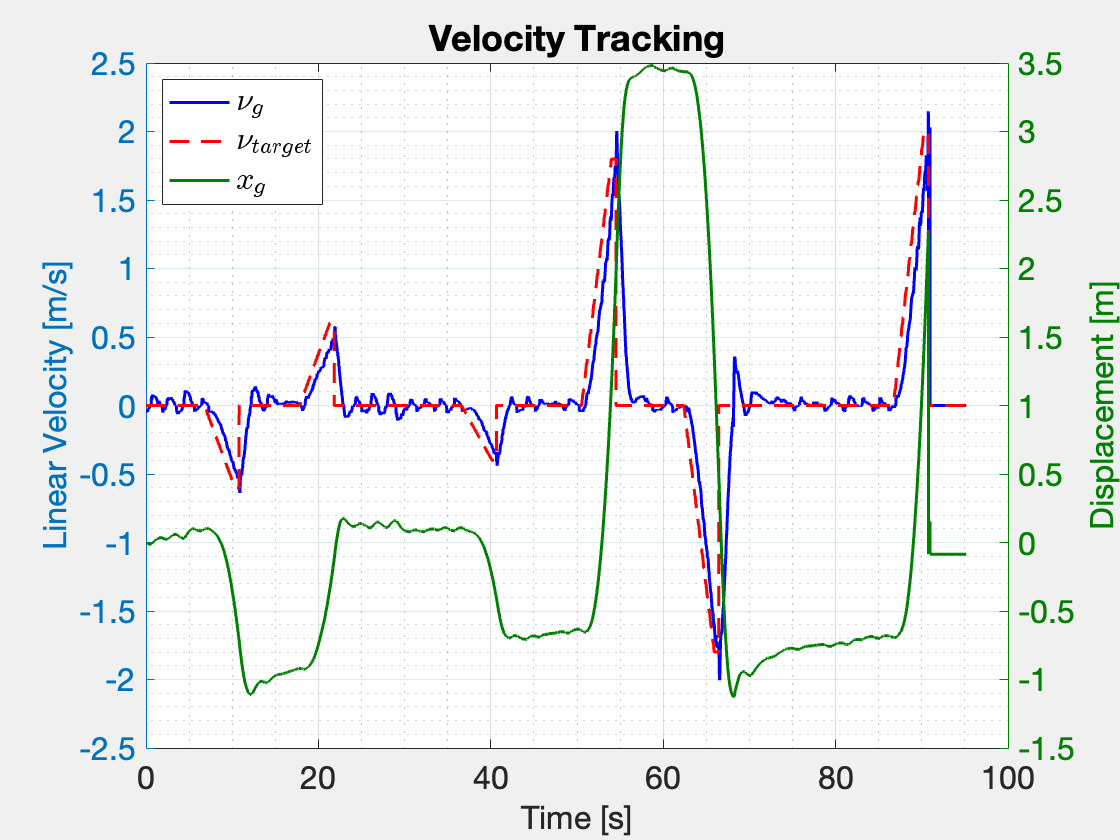

clear; clc; close all;
addpath("utils/")
dataPath = 'DataSets/VelocityControl/velTestRamp2.csv';
[~, timedelta, data] = parseDataSet(dataPath);

start = 1;
stop = 9100;

pitch = data(start:stop,1);
xpos = data(start:stop,21);
xg = data(start:stop,22);
linvel = data(start:stop,15);
linvel_trgt = data(start:stop,16);
num_samples = length(pitch);
dt = mean(timedelta) * 1e-9;
time = (0:num_samples-1) * dt;

fig = figure;

yyaxis('left');
plot(time, linvel, 'b', 'LineWidth', 1.5); hold on;
plot(time, linvel_trgt, 'r--', 'LineWidth', 1.5);
ylabel('Linear Velocity [m/s]')

yyaxis('right');
plot(time, xg - xg(1), 'Color', [0 0.5 0], 'LineWidth', 1.5);
ylabel('Displacement [m]')
ax = gca;
ax.YColor = [0 0.5 0];
% --- Axis and labels ---
xlabel('Time [s]', 'FontSize', 14)
grid on; grid minor;

legend( ...
    {'$\nu_g$', '$\nu_{target}$', '$x_g$'}, ...
    'Interpreter','latex', ...
    'Location','northwest')


fontsize(16, 'points');
plottitle = "Velocity Tracking";
title(plottitle, 'FontSize', 18)
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plottitle + ".pdf");
exportgraphics(fig, filepath);
set(gcf,'Visible', 'on');